% -----------------------------------------------------------------------------------
% -- Big Data and Data Mining (CI7524_A_TB1_25): Course Work --
% -----------------------------------------------------------------------------------

% -- Script about: EDA & Data classification models

% -----------------------------------------------------------------------------------
% 1. Data Handling

% Loading the data (view csv)
data = readtable("vw_patients_final_cte.xlsx")

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________



% Know the size of the data
data_size = size(data)

data_size =        10000          19



% Understand the dataset
head(data)

      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ______________    


% Statistical summary of the data
summary(data)


data: 10000×19 table

Variables:

    PATIENT_ID: cell array of character vectors
    GENDER: cell array of character vectors
    AGE: double
    AGE_FLAG: cell array of character vectors
    SYS_BP: double
    DIAS_BP: double
    SYS_BP_CHANGE: double
    DIAS_BP_CHANGE: double
    PULSE_PRESSURE: double
    CHL_TOT_CHANGE: double
    CHL_HDL_CHANGE: double
    MOTORWAY_RISK_BAND: cell array of character vectors
    FAMILY_HISTORY_ASTHMA: double
    DIABETES_FLAG: double
    SMOKER_FLAG: double
    CVD_MEDS_FLAG: double
    HYPERTENSION_FLAG: double
    COMORBIDITY_INDEX: double
    ASTHMA_WORSENED: double

Statistics for applicable variables:

     


% Convert appropriate columns to categorical
data.GENDER = categorical(data.GENDER)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.SMOKER_FLAG = categorical(data.SMOKER_FLAG)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.DIABETES_FLAG = categorical(data.DIABETES_FLAG)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.CVD_MEDS_FLAG = categorical(data.CVD_MEDS_FLAG)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.HYPERTENSION_FLAG = categorical(data.HYPERTENSION_FLAG)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.MOTORWAY_RISK_BAND = categorical(data.MOTORWAY_RISK_BAND)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.FAMILY_HISTORY_ASTHMA = categorical(data.FAMILY_HISTORY_ASTHMA)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________

data.ASTHMA_WORSENED = categorical(data.ASTHMA_WORSENED)

data = 10000×19 table
      PATIENT_ID      GENDER    AGE      AGE_FLAG      SYS_BP    DIAS_BP    SYS_BP_CHANGE    DIAS_BP_CHANGE    PULSE_PRESSURE    CHL_TOT_CHANGE    CHL_HDL_CHANGE    MOTORWAY_RISK_BAND    FAMILY_HISTORY_ASTHMA    DIABETES_FLAG    SMOKER_FLAG    CVD_MEDS_FLAG    HYPERTENSION_FLAG    COMORBIDITY_INDEX    ASTHMA_WORSENED
    ______________    ______    ___    ____________    ______    _______    _____________    ______________    ______________    ______________    ___________



% verifying the datatypes of the features
varfun(@class,data)

ans = 1×19 table
    class_PATIENT_ID    class_GENDER    class_AGE    class_AGE_FLAG    class_SYS_BP    class_DIAS_BP    class_SYS_BP_CHANGE    class_DIAS_BP_CHANGE    class_PULSE_PRESSURE    class_CHL_TOT_CHANGE    class_CHL_HDL_CHANGE    class_MOTORWAY_RISK_BAND    class_FAMILY_HISTORY_ASTHMA    class_DIABETES_FLAG    class_SMOKER_FLAG    class_CVD_MEDS_FLAG    class_HYPERTENSION_FLAG    class_COMORBIDITY_INDEX    class_ASTHMA_WORSENED
    ________________    ____________    _________    ______________    ____________    _____________    ___________________</

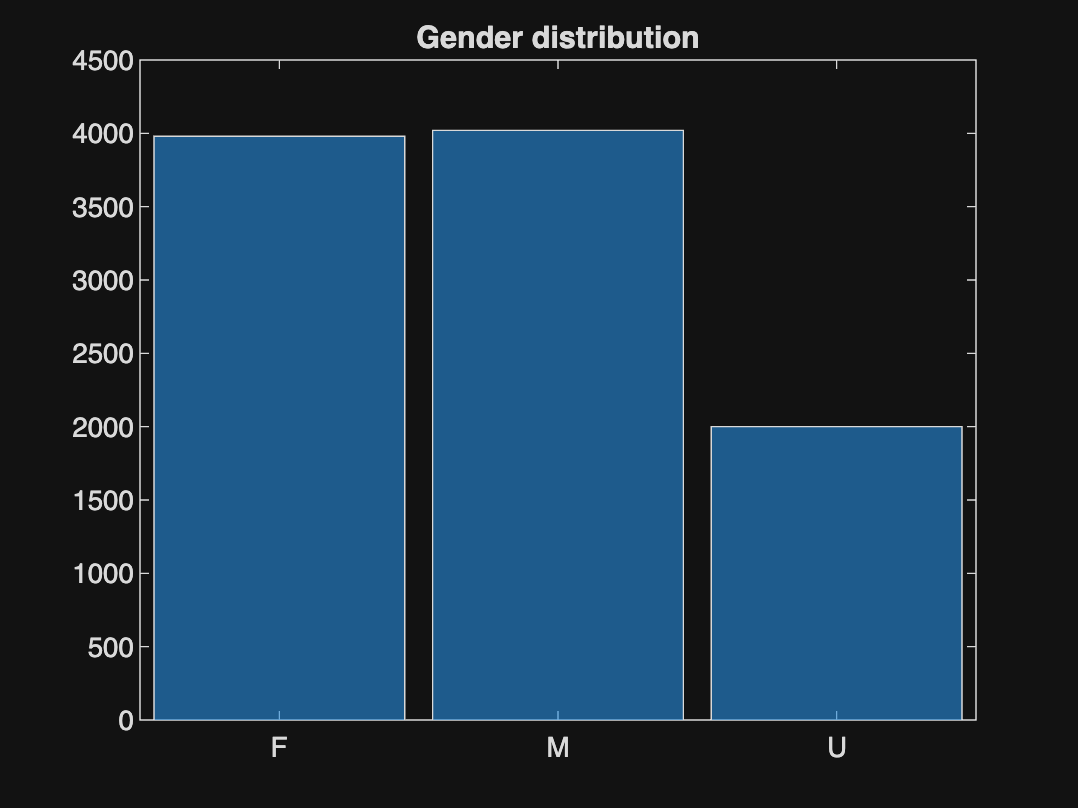


% 2. Basic Exploratory Data Analysis (EDA)

% 2.1. Histogram 
% Gender distribution
figure;
histogram(data.GENDER);
title('Gender distribution')

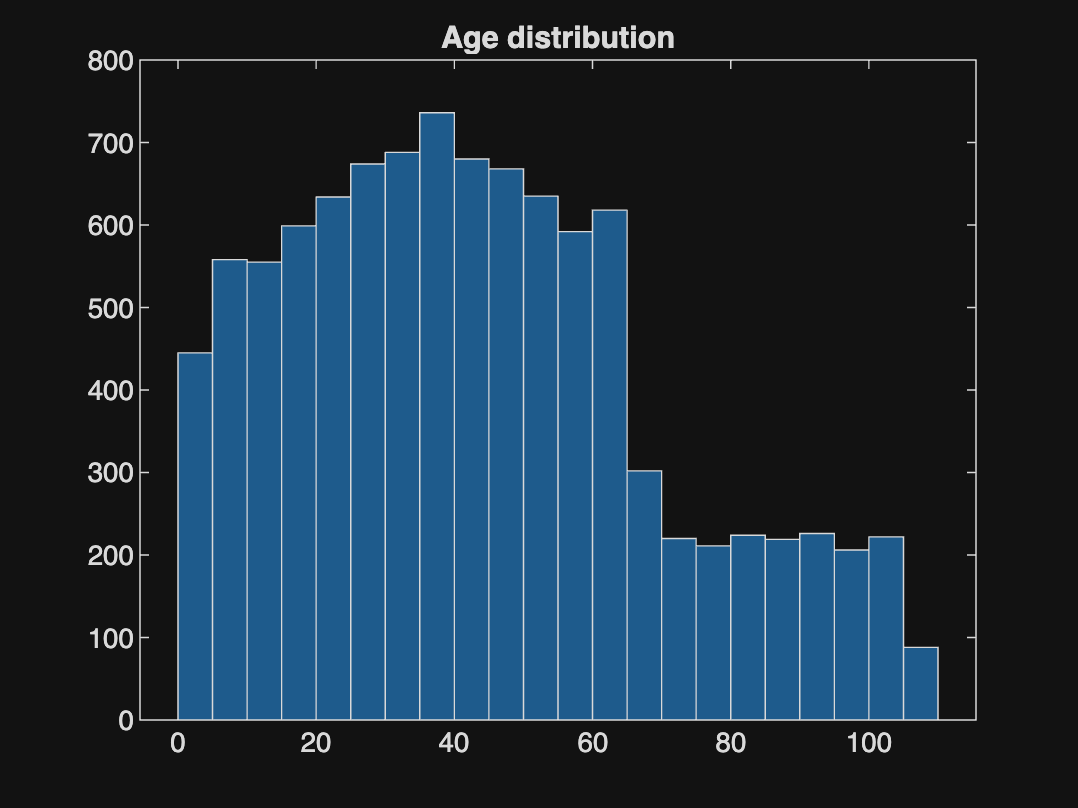

% Age distribution
figure;
histogram(data.AGE);
title('Age distribution')

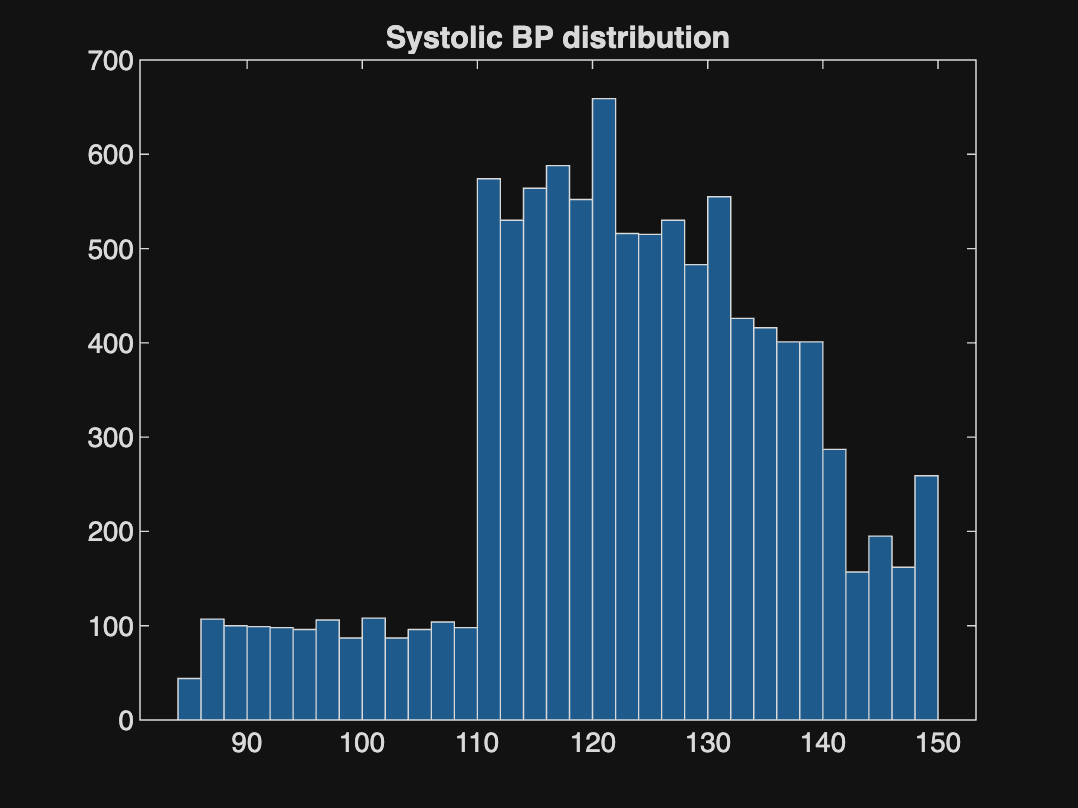


% Systolic BP distribution
figure;
histogram(data.SYS_BP);
title('Systolic BP distribution')

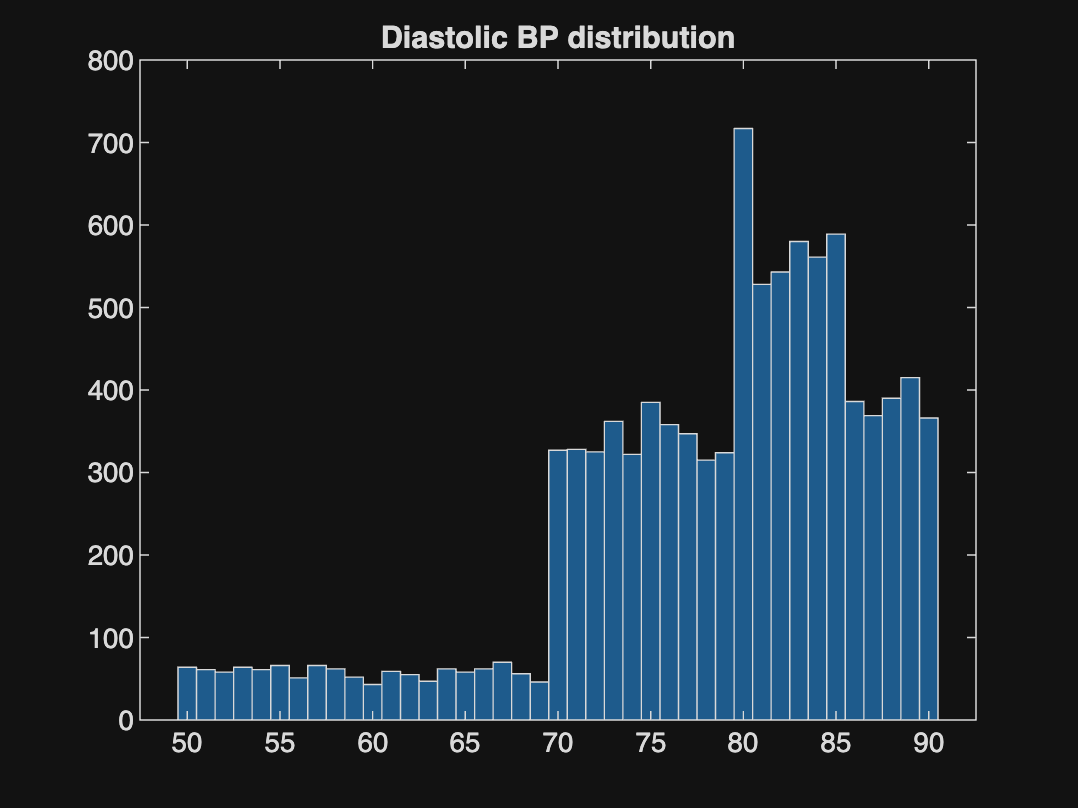


% Diastolic BP distribution
figure;
histogram(data.DIAS_BP);
title('Diastolic BP distribution')

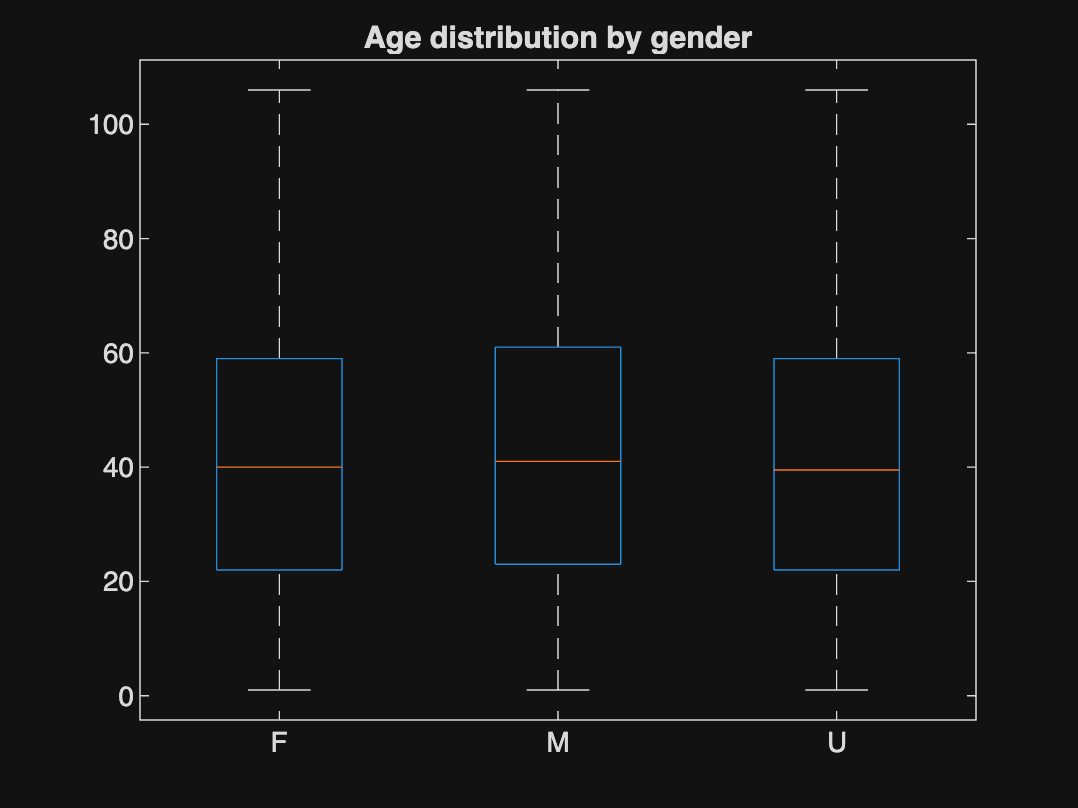


% 2.2. Box plot 
%  age by gender
figure;
boxplot(data.AGE, data.GENDER)
title('Age distribution by gender')

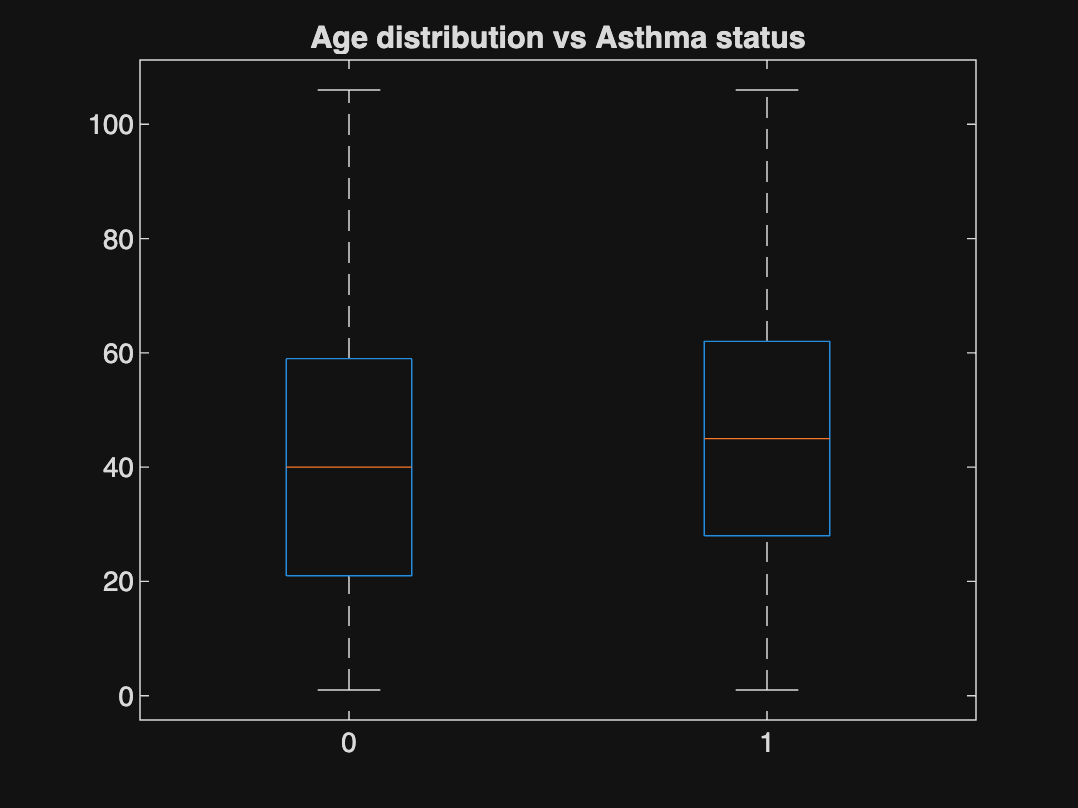


% age by asthma worsened
figure;
boxplot(data.AGE, data.ASTHMA_WORSENED)
title('Age distribution vs Asthma status')

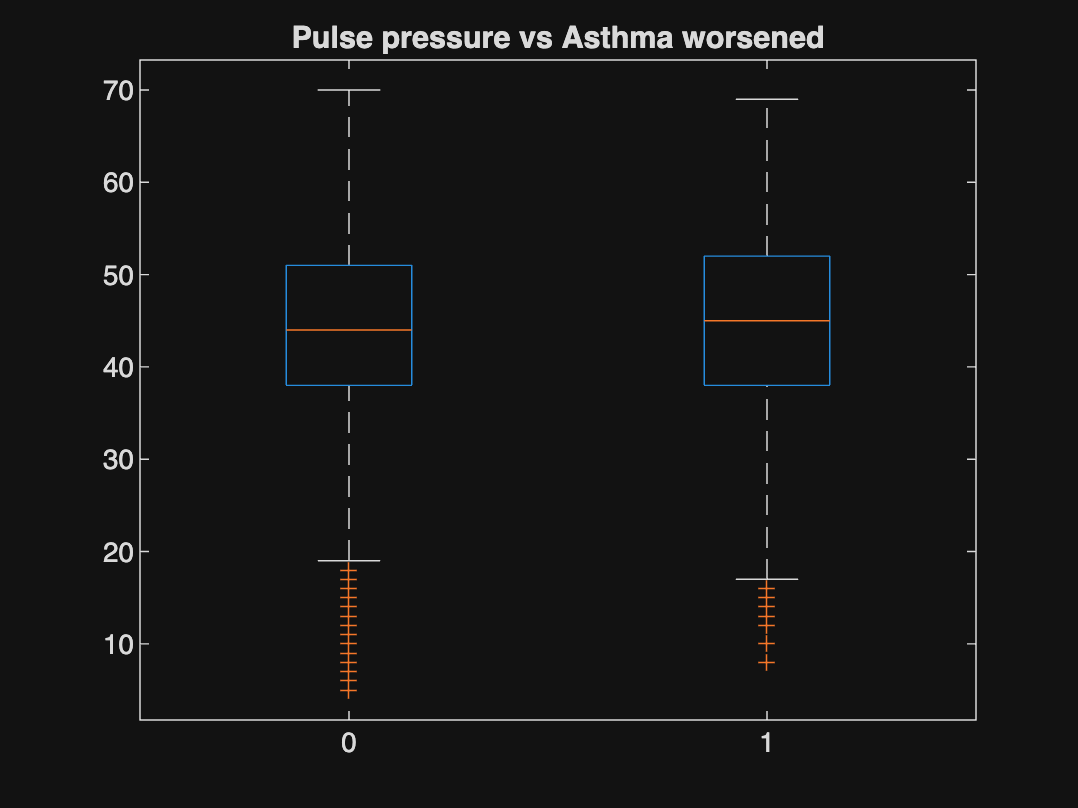


% Pulse pressure vs asthma worsened
figure;
boxplot(data.PULSE_PRESSURE, data.ASTHMA_WORSENED)
title('Pulse pressure vs Asthma worsened')

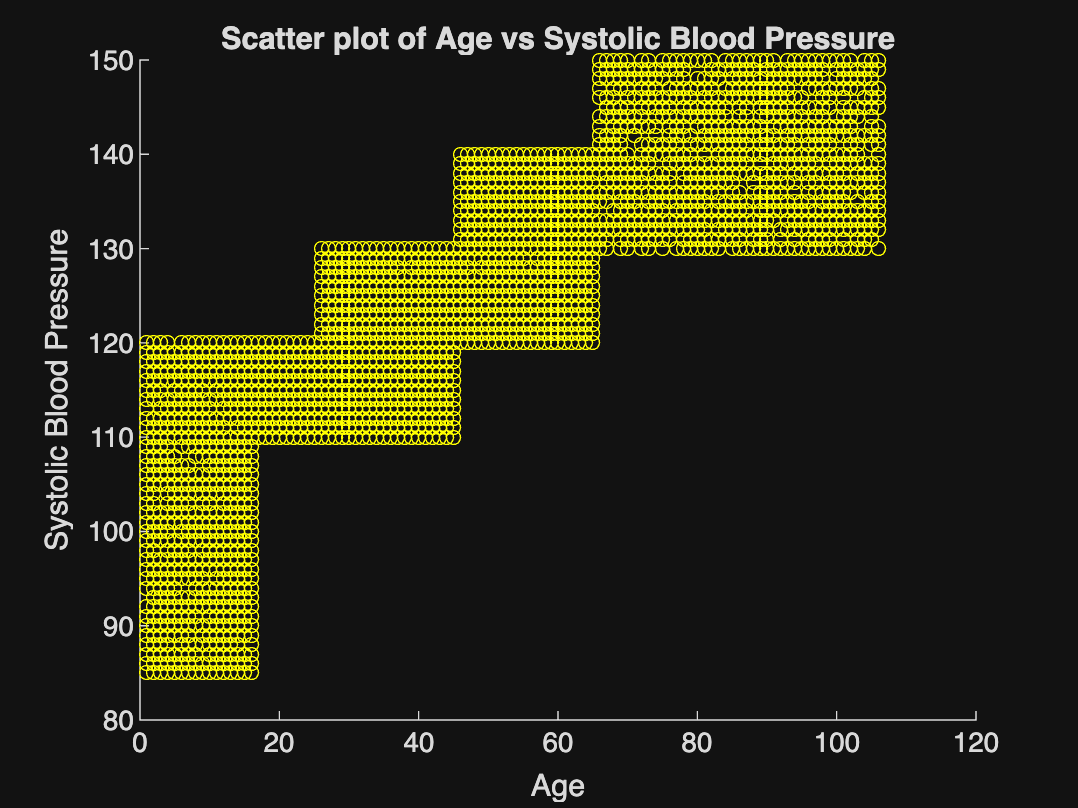


% 2.3 Scatter plot 
% age vs systolic BP
figure;
scatter(data.AGE, data.SYS_BP,25,"yellow");
xlabel('Age');
ylabel('Systolic Blood Pressure');
title('Scatter plot of Age vs Systolic Blood Pressure');

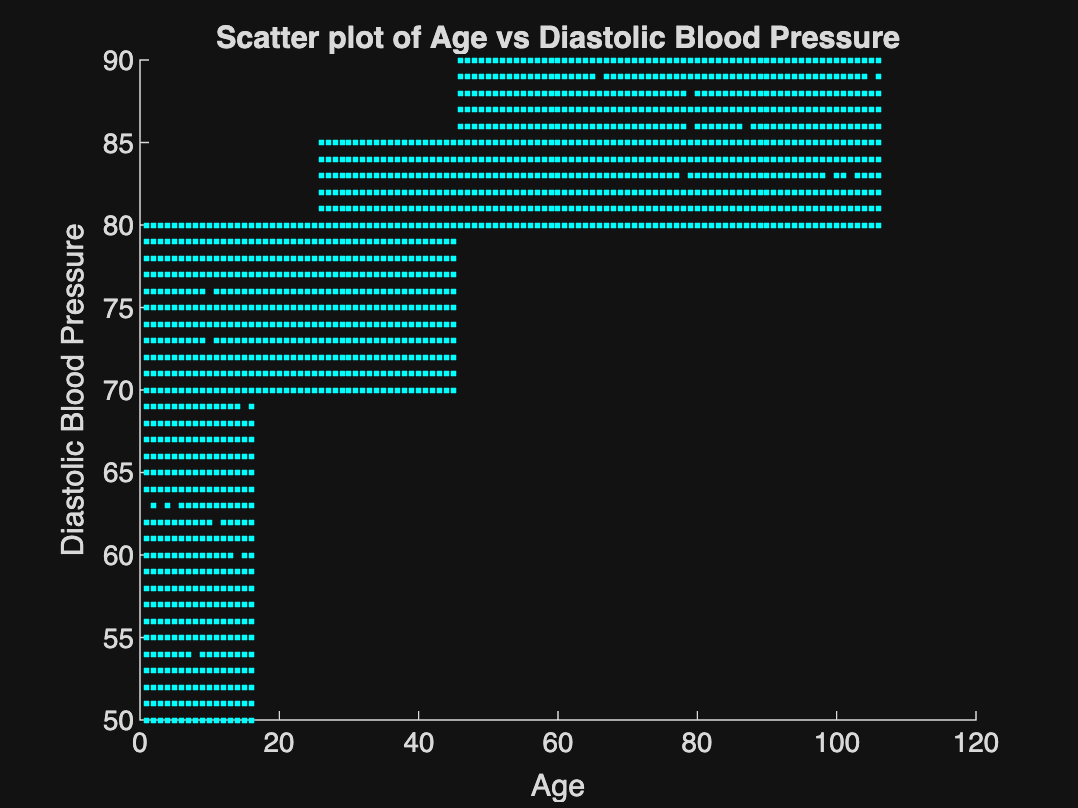


% age vs diastolic BP
figure;
scatter(data.AGE, data.DIAS_BP,"cyan",".");
xlabel('Age');
ylabel('Diastolic Blood Pressure');
title('Scatter plot of Age vs Diastolic Blood Pressure');


% 3. Data partitioning (cvpartition)

% Define predictors
X = data(:, [
    "AGE", "GENDER", "SMOKER_FLAG", "MOTORWAY_RISK_BAND", ...
    "FAMILY_HISTORY_ASTHMA", "DIABETES_FLAG", "COMORBIDITY_INDEX", ...
    "CVD_MEDS_FLAG", "HYPERTENSION_FLAG", "SYS_BP_CHANGE", ...
    "DIAS_BP_CHANGE", "PULSE_PRESSURE", "SYS_BP", "DIAS_BP", ...
    "CHL_HDL_CHANGE", "CHL_TOT_CHANGE"
]);

% target variable
Y = data.ASTHMA_WORSENED

Y = 10000×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 



% X = data(:, predictors);
% Y = data(targetVar);


% Partitioning the data using cvpartition
cv = cvpartition(Y, 'HoldOut', 0.3)

cv = Hold-out cross validation partition
    NumObservations: 10000
        NumTestSets: 1
          TrainSize: 7000
           TestSize: 3000
           IsCustom: 0
          IsGrouped: 0
       IsStratified: 1


  Properties, Methods




% Extracting the training and testing splits
train_spl = training(cv)

train_spl = 10000×1 logical array
   0
   0
   1
   1
   0
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1


test_spl = test(cv)

test_spl = 10000×1 logical array
   1
   1
   0
   0
   1
   0
   0
   1
   0
   0
   0
   1
   0
   0
   0




% Preparing training and test datasets
XTrain = X(train_spl, :);
YTrain = Y(train_spl);

XTest = X(test_spl, :);
YTest = Y(test_spl)

YTest = 3000×1 categorical array
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 




% Final split results
fprintf('Training of predictors: %d records\n', size(XTrain));

Training of predictors: 7000 records
Training of predictors: 16 records


fprintf('Testing of predictors: %d records\n', size(XTest));

Testing of predictors: 3000 records
Testing of predictors: 16 records



fprintf('Training of target variable: %d records\n', size(YTrain));

Training of target variable: 7000 records
Training of target variable: 1 records


fprintf('Testing of target variable: %d records\n', size(YTest));

Testing of target variable: 3000 records
Testing of target variable: 1 records



Decision Tree model Results:
Accuracy : 78.70%
Precision: 0.23
Recall   : 0.21


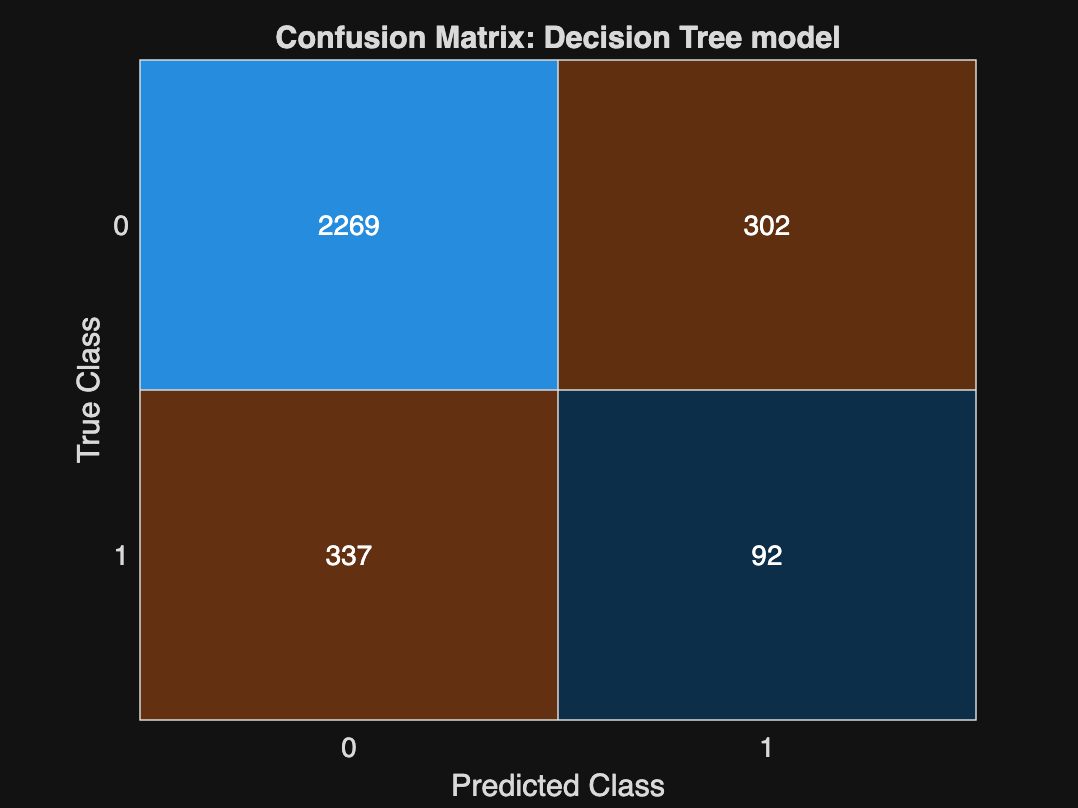

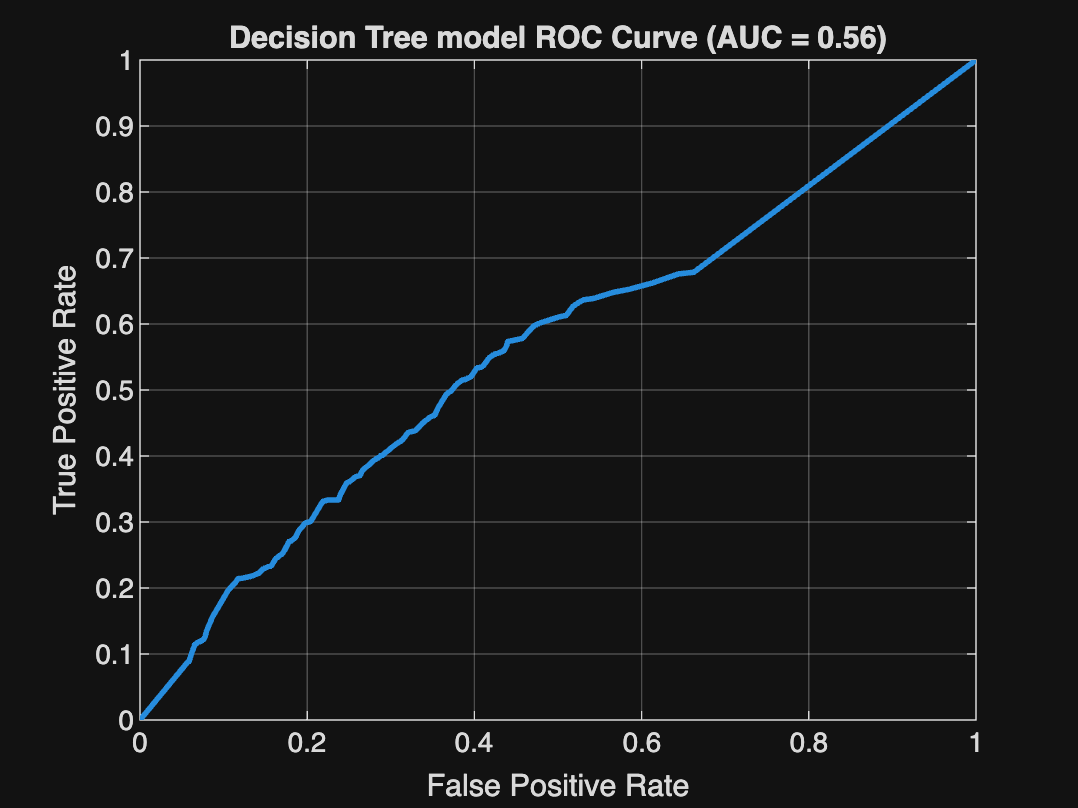

% Common function to evaluate all the models at once

function evaluateModel(YTrue, YPred, scores, modelName)

    % Force same categorical type
    YTrue = categorical(YTrue, {'0','1'});
    YPred = categorical(YPred, {'0','1'});


    % Confusion matrix
    [C,~] = confusionmat(YTrue, YPred);

    TN = C(1,1);


Logistic Regression model Results:
Accuracy : 85.73%
Precision: 0.53
Recall   : 0.02


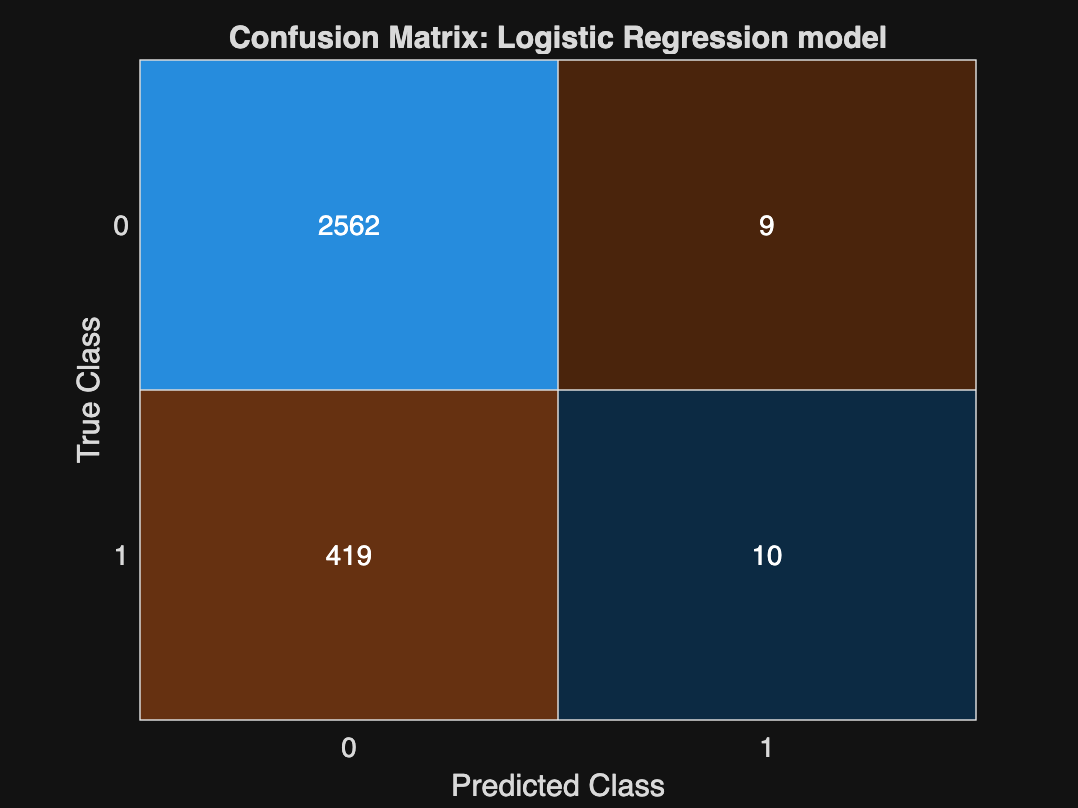

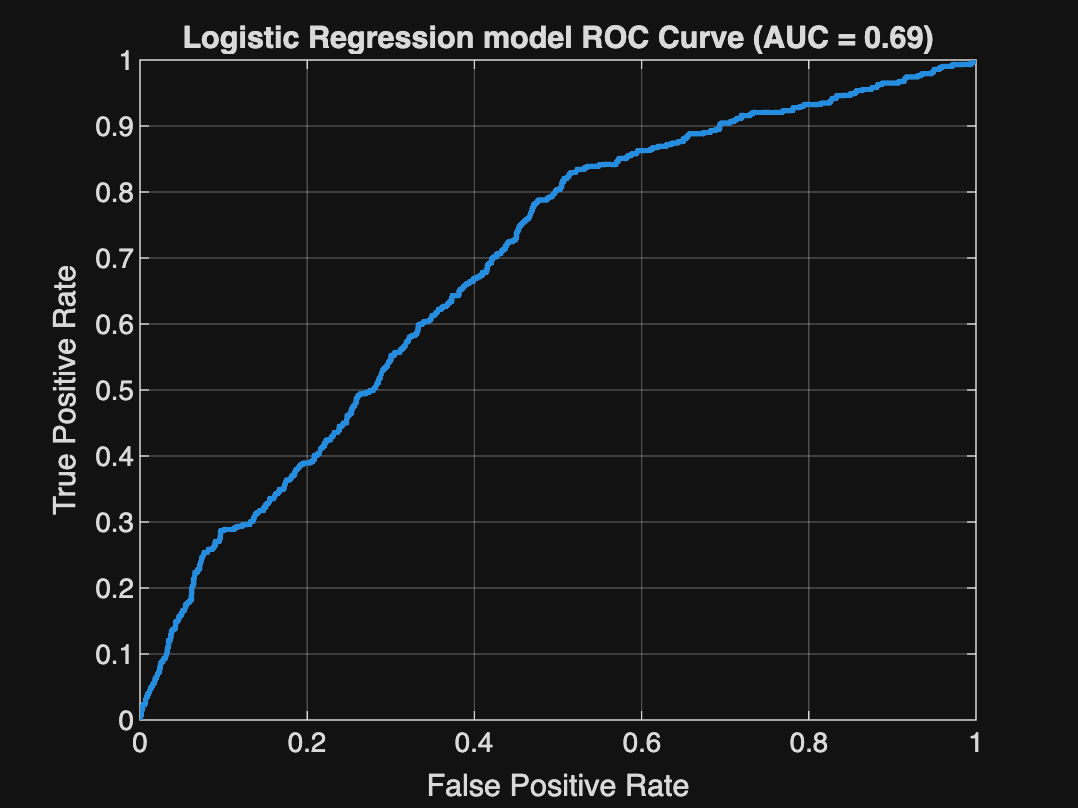

    FP = C(1,2);
    FN = C(2,1);
    TP = C(2,2);

    accuracy  = (TP + TN) / sum(C(:));


Random Forest Results:
Accuracy : 85.40%
Precision: 0.34
Recall   : 0.02


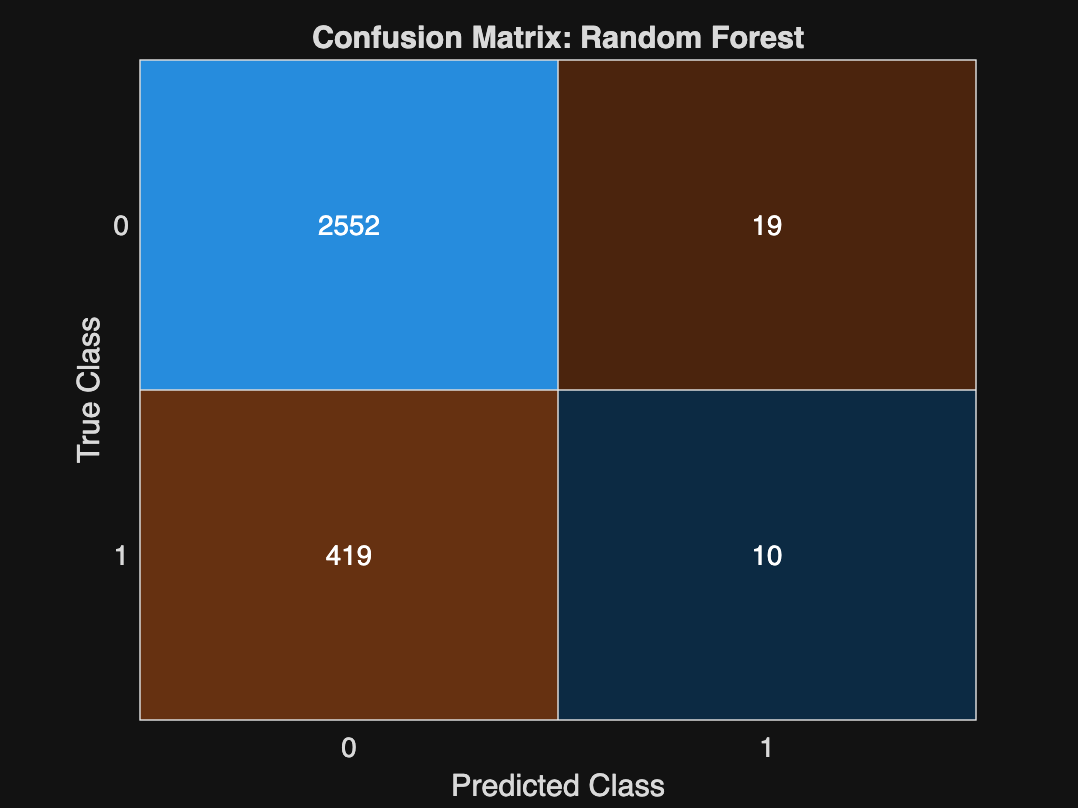

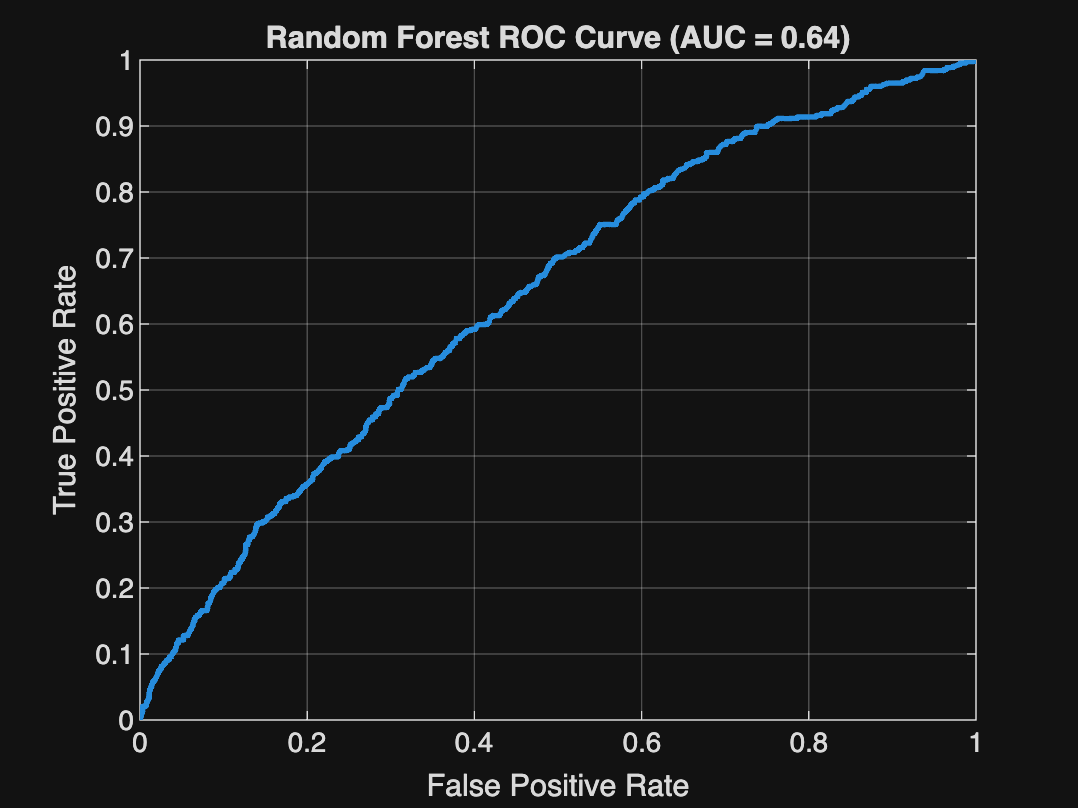

    precision = TP / (TP + FP);
    recall    = TP / (TP + FN);

    fprintf('\n%s Results:\n', modelName);
    fprintf('Accuracy : %.2f%%\n', accuracy * 100);
    fprintf('Precision: %.2f\n', precision);
    fprintf('Recall   : %.2f\n', recall);

    % Confusion matrix plot
    figure;

    confusionchart(YTrue, YPred);
    title(['Confusion Matrix: ', modelName]);

    % ROC + AUC
    [Xroc, Yroc, ~, AUC] = perfcurve(YTrue, scores, '1');
    figure;
    plot(Xroc, Yroc, 'LineWidth', 2);
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    title([modelName, ' ROC Curve (AUC = ', num2str(AUC,'%.2f'), ')']);
    grid on;

end


% 4. Model Training

% 4.1 Decision tree
DT_mdl = fitctree(XTrain, YTrain);

[predDT, scoreDT]= predict(DT_mdl, XTest);
probDT = scoreDT(:, 2);

evaluateModel(YTest, predDT, probDT, 'Decision Tree model')


% 4.2 Logistic regression 
LR_mdl = fitglm(XTrain, YTrain, 'Distribution', 'binomial', 'Link', 'logit');

probLR = predict(LR_mdl, XTest);
predLR = categorical(probLR > 0.5, [false, true], {'0', '1'});

evaluateModel(YTest, predLR, probLR, 'Logistic Regression model');


% 4.3 Random forest
mdlRF = TreeBagger(100, XTrain, YTrain, 'Method', 'classification');

[predRF, scoreRF] = predict(mdlRF, XTest);
predRF = categorical(predRF, {'0','1'});
probRF = scoreRF(:,2);

evaluateModel(YTest, predRF, probRF, 'Random Forest');

